# One-Legged Hopping Robot

#### Parameters

clear all;
close all;
clc

M1=1; % Leg mass [kg]
M2=10; % Body mass [kg]

I1=1; % Leg moment of Inertia [kg-m^2]
I2=10; %Body moment of Inertia [kg-m^2]

r1=0.5; % [m]
r2=0.4; % [m]

k0=1; % [m]
KL=10^3; % [Nt/m]

KL2=60000;%60000; % [Nt/m]
BL2=220;%220; % [Nt-s/m]

KG=10^4; % [Nt/m]
BG=75; % [Nt-s/m]

g=9.8;

#### Initial Conditions

chi_0 = 0.07;

ini_theta1=0;
ini_theta1_d=0;

ini_theta2=0;
ini_theta2_d=0;

ini_w=k0 - chi_0;
ini_w_d=0;

ini_x0=0;
ini_x0_d=0;

ini_y0=0.02;
ini_y0_d=0;

ini_x1=ini_x0+r1*sin(ini_theta1);
ini_x1_d=0;

ini_y1=ini_y0+r1*cos(ini_theta1);
ini_y1_d=0;

ini_x2=ini_x1+r2*sin(ini_theta2);
ini_x2_d=0;

ini_y2=ini_y0+ini_w+r2*cos(ini_theta2);
ini_y2_d=0;



#### Theta1_desired for torque control (equation 1)

theta1_des=0;

**Desired system energy to jump to height H (equation 14)**

H=0.5; %[m]
H2=0.8; %[m]
H3=0.4; %[m]
H4=0.7; %[m]
H5=0.1; %[m]
H6=0.6; %[m]
H7=0.2; %[m]
H8=0.8; %[m]

T2_change = 10; % Time at which the height reference is changed [s]
T3_change = 20; % Time at which the height reference is changed [s]
T4_change = 30; % Time at which the height reference is changed [s]
T5_change = 40; % Time at which the height reference is changed [s]
T6_change = 50; % Time at which the height reference is changed [s]
T7_change = 60; % Time at which the height reference is changed [s]
T8_change = 70; % Time at which the height reference is changed [s]


desired_energy = M1*g*(H+r1) + M2*g*(H+k0+r2);
desired_energy2 = M1*g*(H2+r1) + M2*g*(H2+k0+r2);
desired_energy3 = M1*g*(H3+r1) + M2*g*(H3+k0+r2);
desired_energy4 = M1*g*(H4+r1) + M2*g*(H4+k0+r2);
desired_energy5 = M1*g*(H5+r1) + M2*g*(H5+k0+r2);
desired_energy6 = M1*g*(H6+r1) + M2*g*(H6+k0+r2);
desired_energy7 = M1*g*(H7+r1) + M2*g*(H7+k0+r2);
desired_energy8 = M1*g*(H8+r1) + M2*g*(H8+k0+r2);

**SIMULINK**

simtime=10; %simulation time
warning('off')
SimDec=sim('HoppingModel_Vertical',simtime); %Execution of the simulation in Simulink

Found algebraic loop containing: 
HoppingModel_Vertical/One_Legged_Robot/Subsystem_x/Fcn (algebraic variable)
HoppingModel_Vertical/One_Legged_Robot/Subsystem_x/x_dd
HoppingModel_Vertical/One_Legged_Robot/Subsystem_y/Fcn
HoppingModel_Vertical/One_Legged_Robot/Subsystem_y/y_dd
HoppingModel_Vertical/One_Legged_Robot/Subsystem_w/Fcn


Plot of y0,y1,y2 with chi

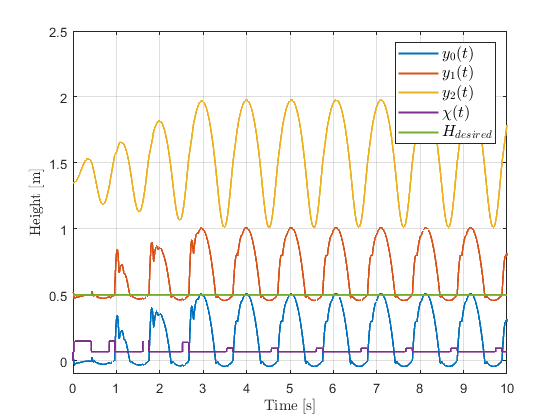

figure(10)
plot(y0.time, y0.data,'Linewidth',1.5)
hold on
plot(y1.time, y1.data,'Linewidth',1.5)
hold on
plot(y2.time, y2.data,'Linewidth',1.5)
hold on
plot(chi.time, chi.data,'Linewidth',1.5)
grid on
plot(y0.time, H*ones(numel(y0.data),1),'Linewidth',1.5)
grid on
ylim([-0.1 2.5])
xlabel('Time [s]','Interpreter','latex')
ylabel('Height [m]','Interpreter','latex')
legend('$y_{0}(t)$','$y_{1}(t)$','$y_{2}(t)$','$\chi(t)$','$H_{desired}$','Fontsize',12,'Interpreter','latex')

**Phase Portrait Plot**

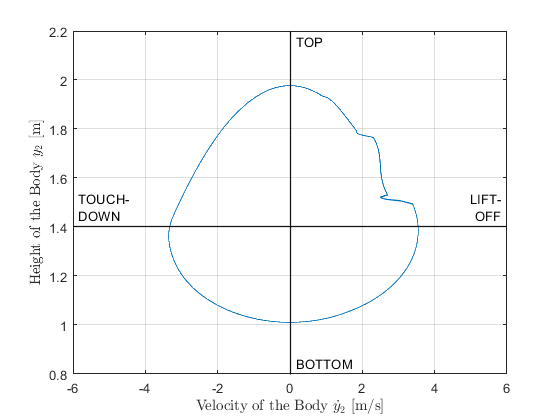

figure(1)
plot(y2d.data(6000:end),y2.data(6000:end),'Linewidth',1)
grid on
%title('Phase Portrait for Vertical Hopping','Interpreter','latex')
ylabel('Height of the Body $y_2$ [m]','Interpreter','latex')
xlabel('Velocity of the Body $\dot{y}_2$ [m/s]','Interpreter','latex')

x1_line = xline(0,'-k',{'TOP'},'HandleVisibility','off','Linewidth',1);
x2_line = xline(0,'-k',{'BOTTOM'},'HandleVisibility','off','Linewidth',1);

x1_line.LabelHorizontalAlignment = 'right';
x2_line.LabelHorizontalAlignment = 'right';
x1_line.LabelVerticalAlignment = 'top';
x2_line.LabelVerticalAlignment = 'bottom';
x1_line.LabelOrientation = 'horizontal';
x2_line.LabelOrientation = 'horizontal';


y1_line = yline(k0+r2,'-k',{'TOUCH-','DOWN'},'HandleVisibility','off','Linewidth',1);
y2_line = yline(k0+r2,'-k',{'LIFT-','OFF'},'HandleVisibility','off','Linewidth',1);

y1_line.LabelHorizontalAlignment = 'left';
y2_line.LabelHorizontalAlignment = 'right';
y1_line.LabelVerticalAlignment = 'top';
y2_line.LabelVerticalAlignment = 'top';

xlim([-6 6])
ylim([0.8 2.2])

**Computation of Total Energy during Flight 1**

ti_f = 3.686;
tf_f = 4.318;

% Potential energy is chosen such that it is zero when the hopper is at
% rest (standing vertically with the leg spring extended to its rest length
% and with the foot just touching the ground), so that:

PE_offset = M1*g*r1 + M2*g*(k0+r2+chi_0);

% Gravitational Potential Energy
PE_g_flight = M1*g*y1.data(ti_f*1000:tf_f*1000) + M2*g*y2.data(ti_f*1000:tf_f*1000);
PE_offset_vec = PE_offset * ones(numel(PE_g_flight),1);

PE_g_flight = PE_g_flight - PE_offset_vec;

% Elastic Potential Energy
k0_vec = k0 * ones(numel(w.data(ti_f*1000:tf_f*1000)),1);
PE_e_M1 = 0.5 * KL * (k0_vec - w.data(ti_f*1000:tf_f*1000) + chi.data(ti_f*1000:tf_f*1000)).^2;
PE_e_flight = PE_e_M1;% + 0.5*KG*(y0.data(ti_f*1000:tf_f*1000)).^2;

% Kinetic Energy
KE_flight = 0.5*M1*(y1d.data(ti_f*1000:tf_f*1000)).^2 + 0.5*M2*(y2d.data(ti_f*1000:tf_f*1000)).^2;

%Total Energy
T_Energy_flight = (M2/(M1+M2))*(PE_g_flight + PE_e_flight + KE_flight);



**Computation of Total Energy during Stance 1**

ti_s = 4.319;
tf_s = 4.719;

% Gravitational Potential Energy
PE_g_stance = M1*g*y1.data(ti_s*1000:tf_s*1000) + M2*g*y2.data(ti_s*1000:tf_s*1000);

PE_offset_vec = PE_offset * ones(numel(PE_g_stance),1);

PE_g_stance = PE_g_stance - PE_offset_vec;

% Elastic Potential Energy
k0_vec = k0 * ones(numel(w.data(ti_s*1000:tf_s*1000)),1);
PE_e_M1 = 0.5 * KL * (k0_vec - w.data(ti_s*1000:tf_s*1000) + chi.data(ti_s*1000:tf_s*1000)).^2;
PE_e_stance = PE_e_M1 + 0.5*KG*(y0.data(ti_s*1000:tf_s*1000)).^2;

% Kinetic Energy
KE_stance = 0.5*M1*(y1d.data(ti_s*1000:tf_s*1000)).^2 + 0.5*M2*(y2d.data(ti_s*1000:tf_s*1000)).^2;

%Total Energy
T_Energy_stance = PE_g_stance + PE_e_stance + KE_stance;

**Computation of Total Energy during Flight 2**

ti_f2 = 4.72;
tf_f2 = 5.352;

% Gravitational Potential Energy
PE_g_flight_2 = M1*g*y1.data(ti_f2*1000:tf_f2*1000) + M2*g*y2.data(ti_f2*1000:tf_f2*1000);

PE_offset_vec = PE_offset * ones(numel(PE_g_flight_2),1);

PE_g_flight_2 = PE_g_flight_2 - PE_offset_vec;

% Elastic Potential Energy
k0_vec = k0 * ones(numel(w.data(ti_f2*1000:tf_f2*1000)),1);
PE_e_M1_2 = 0.5 * KL * (k0_vec - w.data(ti_f2*1000:tf_f2*1000) + chi.data(ti_f2*1000:tf_f2*1000)).^2;
PE_e_flight_2 = PE_e_M1_2;% + 0.5*KG*(y0.data(ti_f*1000:tf_f*1000)).^2;

% Kinetic Energy
KE_flight_2 = 0.5*M1*(y1d.data(ti_f2*1000:tf_f2*1000)).^2 + 0.5*M2*(y2d.data(ti_f2*1000:tf_f2*1000)).^2;

%Total Energy
T_Energy_flight_2 = (M2/(M1+M2))* (PE_g_flight_2 + PE_e_flight_2 + KE_flight_2);

**Computation of Total Energy during Stance 2**

ti_s2 = 5.353;
tf_s2 = 5.751;

% Gravitational Potential Energy
PE_g_stance_2 = M1*g*y1.data(ti_s2*1000:tf_s2*1000) + M2*g*y2.data(ti_s2*1000:tf_s2*1000);

PE_offset_vec = PE_offset * ones(numel(PE_g_stance_2),1);

PE_g_stance_2 = PE_g_stance_2 - PE_offset_vec;

% Elastic Potential Energy
k0_vec = k0 * ones(numel(w.data(ti_s2*1000:tf_s2*1000)),1);
PE_e_M1_2 = 0.5 * KL * (k0_vec - w.data(ti_s2*1000:tf_s2*1000) + chi.data(ti_s2*1000:tf_s2*1000)).^2;
PE_e_stance_2 = PE_e_M1_2 + 0.5*KG*(y0.data(ti_s2*1000:tf_s2*1000)).^2;

% Kinetic Energy
KE_stance_2 = 0.5*M1*(y1d.data(ti_s2*1000:tf_s2*1000)).^2 + 0.5*M2*(y2d.data(ti_s2*1000:tf_s2*1000)).^2;

%Total Energy
T_Energy_stance_2 = PE_g_stance_2 + PE_e_stance_2 + KE_stance_2;

**Total Energy Stance and flight**

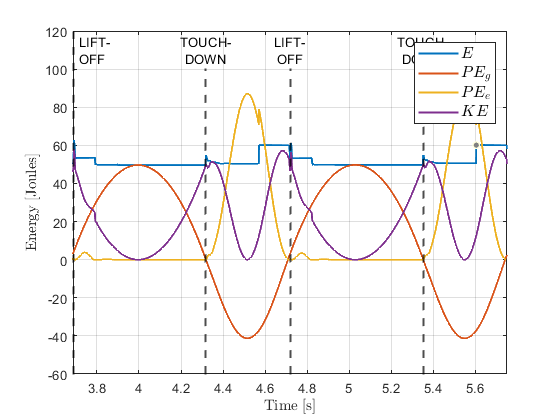

T_Energy_SF = [T_Energy_flight; T_Energy_stance; T_Energy_flight_2; T_Energy_stance_2];
PE_g_SF = (M2/(M1+M2))*[PE_g_flight; PE_g_stance; PE_g_flight_2; PE_g_stance_2];
PE_e_SF = (M2/(M1+M2))*[PE_e_flight; PE_e_stance; PE_e_flight_2; PE_e_stance_2];
KE_SF = (M2/(M1+M2))*[KE_flight; KE_stance; KE_flight_2; KE_stance_2];

figure(2)
plot(y0.time(ti_f*1000:tf_s2*1000), T_Energy_SF,'Linewidth',1.5)
hold on
plot(y0.time(ti_f*1000:tf_s2*1000), PE_g_SF,'Linewidth',1.5)
hold on
plot(y0.time(ti_f*1000:tf_s2*1000), PE_e_SF,'Linewidth',1.5)
hold on
plot(y0.time(ti_f*1000:tf_s2*1000), KE_SF,'Linewidth',1.5)
grid on
xlabel('Time [s]','Interpreter','latex')
ylabel('Energy [Joules]','Interpreter','latex')
legend('$E$','$PE_g$','$PE_e$','$KE$','Fontsize',12,'Interpreter','latex')

x1_line = xline(ti_f,'--k',{'LIFT-','OFF'},'HandleVisibility','off','Linewidth',1.5);
x2_line = xline(tf_f,'--k',{'TOUCH-','DOWN'},'HandleVisibility','off','Linewidth',1.5);
x3_line = xline(ti_f2,'--k',{'LIFT-','OFF'},'HandleVisibility','off','Linewidth',1.5);
x4_line = xline(tf_f2,'--k',{'TOUCH-','DOWN'},'HandleVisibility','off','Linewidth',1.5);

x1_line.LabelHorizontalAlignment = 'right';
x2_line.LabelHorizontalAlignment = 'center';
x3_line.LabelHorizontalAlignment = 'center';
x4_line.LabelHorizontalAlignment = 'center';

x1_line.LabelOrientation = 'horizontal';
x2_line.LabelOrientation = 'horizontal';
x3_line.LabelOrientation = 'horizontal';
x4_line.LabelOrientation = 'horizontal';

xlim([ti_f,tf_s2])
ylim([-60 120])

Plot y0

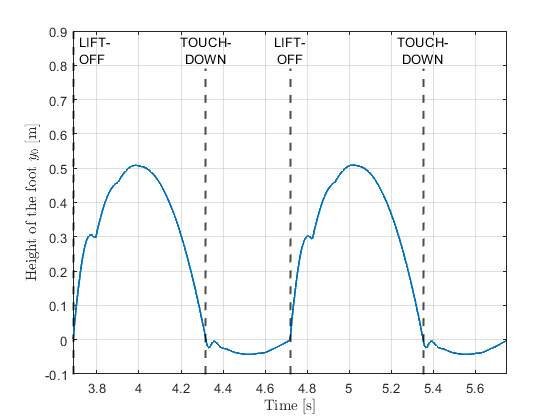

figure(3)
plot(y0.time(ti_f*1000:tf_s2*1000),y0.data(ti_f*1000:tf_s2*1000),'Linewidth',1.5)
ylim([-0.1 0.9])
xlim([ti_f,tf_s2])
grid on
ylabel('Height of the foot $y_0$ [m]','Interpreter','latex')
xlabel('Time [s]','Interpreter','latex')

x1_line = xline(ti_f,'--k',{'LIFT-','OFF'},'HandleVisibility','off','Linewidth',1.5);
x2_line = xline(tf_f,'--k',{'TOUCH-','DOWN'},'HandleVisibility','off','Linewidth',1.5);
x3_line = xline(ti_f2,'--k',{'LIFT-','OFF'},'HandleVisibility','off','Linewidth',1.5);
x4_line = xline(tf_f2,'--k',{'TOUCH-','DOWN'},'HandleVisibility','off','Linewidth',1.5);

x1_line.LabelHorizontalAlignment = 'right';
x2_line.LabelHorizontalAlignment = 'center';
x3_line.LabelHorizontalAlignment = 'center';
x4_line.LabelHorizontalAlignment = 'center';

x1_line.LabelOrientation = 'horizontal';
x2_line.LabelOrientation = 'horizontal';
x3_line.LabelOrientation = 'horizontal';
x4_line.LabelOrientation = 'horizontal';

**SIMULINK (Simulation for 8 desired heights 80 seconds of simulation)**

simtime=80; %simulation time
SimDec=sim('HoppingModel_Vertical',simtime); %Execution of the simulation in Simulink

Found algebraic loop containing: 
HoppingModel_Vertical/One_Legged_Robot/Subsystem_x/Fcn (algebraic variable)
HoppingModel_Vertical/One_Legged_Robot/Subsystem_x/x_dd
HoppingModel_Vertical/One_Legged_Robot/Subsystem_y/Fcn
HoppingModel_Vertical/One_Legged_Robot/Subsystem_y/y_dd
HoppingModel_Vertical/One_Legged_Robot/Subsystem_w/Fcn


Plot of y0,y2 with chi

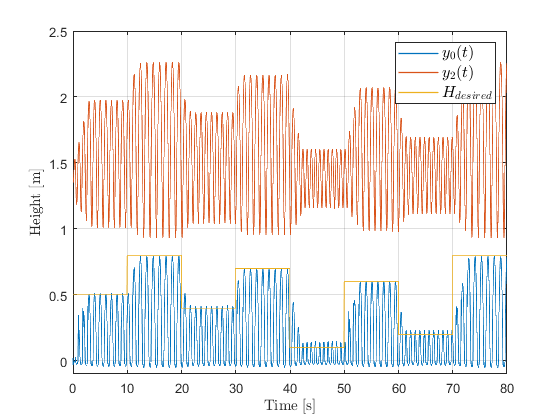

figure(11)
plot(y0.time, y0.data,'Linewidth',1)
hold on
plot(y2.time, y2.data,'Linewidth',1)
hold on
plot(Desired_H.time,Desired_H.data,'Linewidth',1)
grid on
ylim([-0.1 2.5])
xlabel('Time [s]','Interpreter','latex')
ylabel('Height [m]','Interpreter','latex')
legend('$y_{0}(t)$','$y_{2}(t)$','$H_{desired}$','Fontsize',12,'Interpreter','latex')

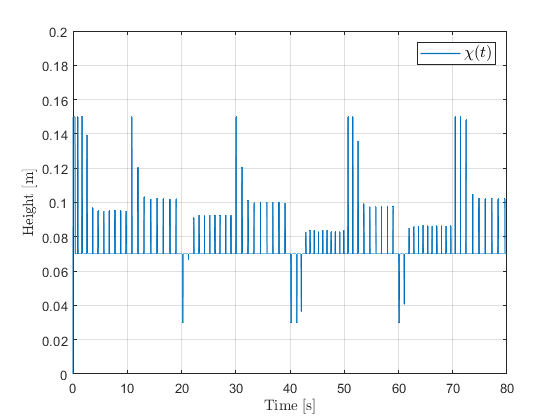


figure(12)
plot(chi.time, chi.data,'Linewidth',1)
grid on
ylim([0 0.2])
xlabel('Time [s]','Interpreter','latex')
ylabel('Height [m]','Interpreter','latex')
legend('$\chi(t)$','Fontsize',12,'Interpreter','latex')